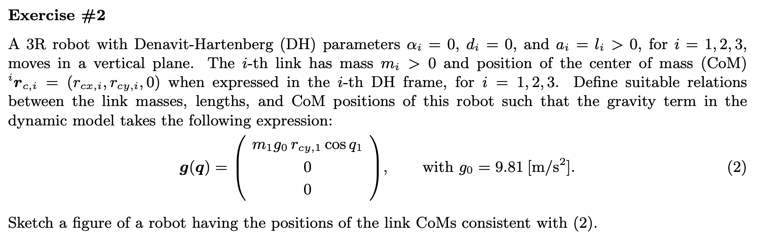

% Symbolic Computation of CoM Positions for a 3R Planar Robot

clear; clc;
syms q1 q2 q3 l1 l2 l3 real
syms rcx1 rcy1 rcx2 rcy2 rcx3 rcy3 real
syms m1 m2 m3 real
syms g0 real
% Define cos and sin for simplicity
c1 = cos(q1); s1 = sin(q1);
c2 = cos(q2); s2 = sin(q2);
c3 = cos(q3); s3 = sin(q3);

c12 = cos(q1 + q2); s12 = sin(q1 + q2);
c123 = cos(q1 + q2 + q3); s123 = sin(q1 + q2 + q3);

% Homogeneous Transformation Matrices using DH parameters
A1 = [c1, -s1, 0, l1*c1;
      s1,  c1, 0, l1*s1;
      0 ,   0, 1,     0;
      0 ,   0, 0,     1];

A2 = [c2, -s2, 0, l2*c2;
      s2,  c2, 0, l2*s2;
      0 ,   0, 1,     0;
      0 ,   0, 0,     1];

A3 = [c3, -s3, 0, l3*c3;
      s3,  c3, 0, l3*s3;
      0 ,   0, 1,     0;
      0 ,   0, 0,     1];

% Compute cumulative transformations
T01 = A1;
T02 = A1 * A2;
T03 = A1 * A2 * A3;

% Center of mass positions in each link frame
rc1_local = [rcx1; rcy1; 0; 1];
rc2_local = [rcx2; rcy2; 0; 1];
rc3_local = [rcx3; rcy3; 0; 1];

% Transform CoMs to base frame
rc1_base = T01 * rc1_local;
rc2_base = T02 * rc2_local;
rc3_base = T03 * rc3_local;

% Display results
disp('r_c1 in base frame:');

r_c1 in base frame:


disp(simplify(rc1_base));

$$\left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\\ 0\\ 1 \end{array}\right)$$


disp('r_c2 in base frame:');

r_c2 in base frame:


disp(simplify(rc2_base));

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+{\mathrm{rcx}}_{2}\,\cos\left(q_{1}+q_{2}\right)-{\mathrm{rcy}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{rcy}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}+q_{2}\right)+{\mathrm{rcx}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0\\ 1 \end{array}\right)$$


disp('r_c3 in base frame:');

r_c3 in base frame:


disp(simplify(rc3_base));

$$\begin{array}{l} \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\sigma_{2}+{\mathrm{rcx}}_{3}\,\sigma_{2}-{\mathrm{rcy}}_{3}\,\sigma_{1}\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcy}}_{3}\,\sigma_{2}+l_{3}\,\sigma_{1}+{\mathrm{rcx}}_{3}\,\sigma_{1}\\ 0\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


% Potential energy for each link

U1 = -m1*g0*rc1_base

$$U1 = \left(\begin{array}{c} -g_{0}\,m_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)\right)\\ -g_{0}\,m_{1}\,\left({\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{1} \end{array}\right)$$

disp('Potential energy of first link')

Potential energy of first link


disp(U1)

$$\left(\begin{array}{c} -g_{0}\,m_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)\right)\\ -g_{0}\,m_{1}\,\left({\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{1} \end{array}\right)$$


U2 = -m2*g0*rc2_base

$$U2 = \begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{1}-{\mathrm{rcy}}_{2}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{2}+{\mathrm{rcy}}_{2}\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

disp('Potential energy of second link')

Potential energy of second link


disp(U2)

$$\begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{1}-{\mathrm{rcy}}_{2}\,\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{2}+{\mathrm{rcy}}_{2}\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$


U3 = -m3*g0*rc3_base

$$U3 = \begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{1}-{\mathrm{rcy}}_{3}\,\sigma_{2}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{3}-l_{3}\,\sin\left(q_{3}\right)\,\sigma_{4}+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -g_{0}\,m_{3}\,\left(l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{2}+{\mathrm{rcy}}_{3}\,\sigma_{1}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{4}+l_{3}\,\sin\left(q_{3}\right)\,\sigma_{3}+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sigma_{3}-\sin\left(q_{3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(q_{3}\right)\,\sigma_{4}+\sin\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$

disp('Potential energy of third link')

Potential energy of third link


disp(U3)

$$\begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{1}-{\mathrm{rcy}}_{3}\,\sigma_{2}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{3}-l_{3}\,\sin\left(q_{3}\right)\,\sigma_{4}+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -g_{0}\,m_{3}\,\left(l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{2}+{\mathrm{rcy}}_{3}\,\sigma_{1}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{4}+l_{3}\,\sin\left(q_{3}\right)\,\sigma_{3}+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sigma_{3}-\sin\left(q_{3}\right)\,\sigma_{4}\\ \sigma_{2}=\cos\left(q_{3}\right)\,\sigma_{4}+\sin\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$



U = U1+U2+U3

$$U = \begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{5}-{\mathrm{rcy}}_{3}\,\sigma_{6}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{7}-l_{3}\,\sin\left(q_{3}\right)\,\sigma_{8}+\sigma_{4}-\sigma_{1}\right)-g_{0}\,m_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)\right)-g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{7}-{\mathrm{rcy}}_{2}\,\sigma_{8}+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4}-\sigma_{1}\right)\\ -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{8}+{\mathrm{rcy}}_{2}\,\sigma_{7}+l_{1}\,\sin\left(q_{1}\right)+\sigma_{3}+\sigma_{2}\right)-g_{0}\,m_{3}\,\left(l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{6}+{\mathrm{rcy}}_{3}\,\sigma_{5}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{8}+l_{3}\,\sin\left(q_{3}\right)\,\sigma_{7}+\sigma_{3}+\sigma_{2}\right)-g_{0}\,m_{1}\,\left({\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{1}-g_{0}\,m_{2}-g_{0}\,m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{5}=\cos\left(q_{3}\right)\,\sigma_{7}-\sin\left(q_{3}\right)\,\sigma_{8}\\ \sigma_{6}=\cos\left(q_{3}\right)\,\sigma_{8}+\sin\left(q_{3}\right)\,\sigma_{7}\\ \sigma_{7}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{8}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$


simplify(U)

$$ans = \begin{array}{l} \left(\begin{array}{c} -g_{0}\,\left(l_{1}\,m_{1}\,\cos\left(q_{1}\right)+l_{1}\,m_{2}\,\cos\left(q_{1}\right)+l_{1}\,m_{3}\,\cos\left(q_{1}\right)+m_{1}\,{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-m_{1}\,{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)+l_{3}\,m_{3}\,\sigma_{2}+m_{3}\,{\mathrm{rcx}}_{3}\,\sigma_{2}-m_{3}\,{\mathrm{rcy}}_{3}\,\sigma_{1}+l_{2}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,m_{3}\,\cos\left(q_{1}+q_{2}\right)+m_{2}\,{\mathrm{rcx}}_{2}\,\cos\left(q_{1}+q_{2}\right)-m_{2}\,{\mathrm{rcy}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)\\ -g_{0}\,\left(m_{1}\,{\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,m_{1}\,\sin\left(q_{1}\right)+l_{1}\,m_{2}\,\sin\left(q_{1}\right)+l_{1}\,m_{3}\,\sin\left(q_{1}\right)+m_{1}\,{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)+m_{3}\,{\mathrm{rcy}}_{3}\,\sigma_{2}+l_{3}\,m_{3}\,\sigma_{1}+m_{3}\,{\mathrm{rcx}}_{3}\,\sigma_{1}+m_{2}\,{\mathrm{rcy}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,m_{3}\,\sin\left(q_{1}+q_{2}\right)+m_{2}\,{\mathrm{rcx}}_{2}\,\sin\left(q_{1}+q_{2}\right)\right)\\ 0\\ -g_{0}\,\left(m_{1}+m_{2}+m_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

disp(U)

$$\begin{array}{l} \left(\begin{array}{c} -g_{0}\,m_{3}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{5}-{\mathrm{rcy}}_{3}\,\sigma_{6}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{7}-l_{3}\,\sin\left(q_{3}\right)\,\sigma_{8}+\sigma_{4}-\sigma_{1}\right)-g_{0}\,m_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{rcy}}_{1}\,\sin\left(q_{1}\right)\right)-g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{7}-{\mathrm{rcy}}_{2}\,\sigma_{8}+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4}-\sigma_{1}\right)\\ -g_{0}\,m_{2}\,\left({\mathrm{rcx}}_{2}\,\sigma_{8}+{\mathrm{rcy}}_{2}\,\sigma_{7}+l_{1}\,\sin\left(q_{1}\right)+\sigma_{3}+\sigma_{2}\right)-g_{0}\,m_{3}\,\left(l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{3}\,\sigma_{6}+{\mathrm{rcy}}_{3}\,\sigma_{5}+l_{3}\,\cos\left(q_{3}\right)\,\sigma_{8}+l_{3}\,\sin\left(q_{3}\right)\,\sigma_{7}+\sigma_{3}+\sigma_{2}\right)-g_{0}\,m_{1}\,\left({\mathrm{rcy}}_{1}\,\cos\left(q_{1}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{rcx}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0\\ -g_{0}\,m_{1}-g_{0}\,m_{2}-g_{0}\,m_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{5}=\cos\left(q_{3}\right)\,\sigma_{7}-\sin\left(q_{3}\right)\,\sigma_{8}\\ \sigma_{6}=\cos\left(q_{3}\right)\,\sigma_{8}+\sin\left(q_{3}\right)\,\sigma_{7}\\ \sigma_{7}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{8}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}$$